assert(endsWith(pwd, "non-ferromagnetic metal disk in time domain"), 'Not in project directory')
addpath('../../DCS_functions')

clear;
close all;

## Distributed Current Source

#### Electromagnet

EM.inner_radius = 3.75e-3; % (m)
EM.outer_radius = 6.00e-3; % (m)
EM.length = 4.00e-3; % length (m)
EM.Nturns = 60;

EM.z = 5.00e-3; % (m)

#### Sensor

Sensor.num = 1;
Sensor.side_length = 0.8e-3;

Sensor.position = [0e-3 2.5e-3]';

#### Model

disk.radius = 30e-3; % (m)
disk.height = 6e-3; % (m)
disk.n_r = 10; % number of elements in r direction
disk.n_z = 10; % number of elements in z direction

r = linspace(0, disk.radius, disk.n_r+1);
z = linspace(-disk.height,0, disk.n_z+1);

Model = BuildModel2D(r,z);

calculate geometry took 0.01 seconds


clear disk r z

Model.conductivity = 1.91e7 * ones(1,Model.num_elms); % (S/m)
Model.relative_permittivity = 1 * ones(1,Model.num_elms); % (1)

#### Governing equation

GoverningEquation = BuildGoveringEquation2D(Model, EM);

build governing equation took 5.51 seconds


#### Solve in time domain

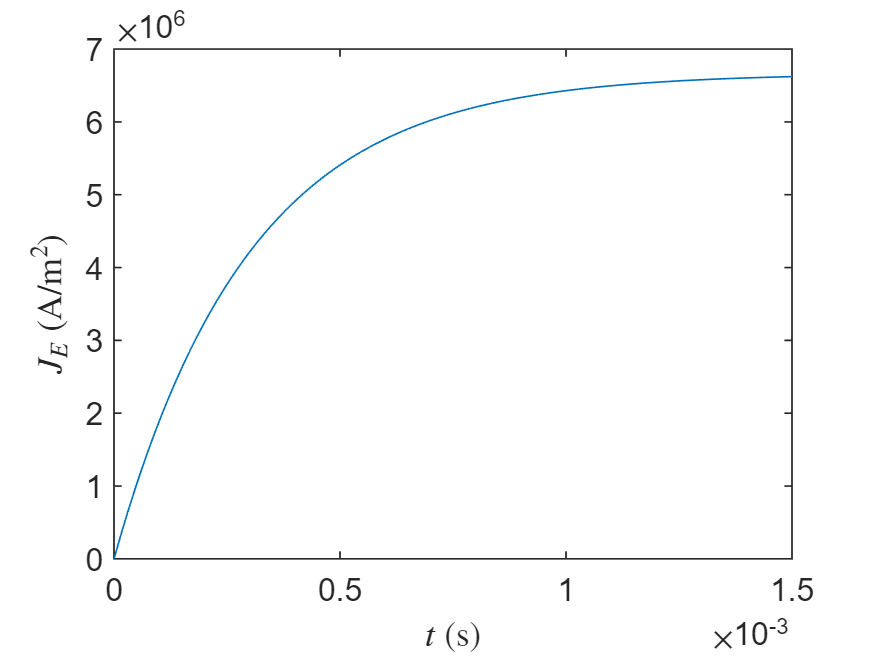

I_E_ss = 1; % (A)
J_E_ss = I_E_ss * EM.Nturns / ((EM.outer_radius-EM.inner_radius)*EM.length); % (A/m^2)
tau = 3e-4; % (s)

EM.time_domain.current_density = @(t) J_E_ss * (1 - exp(-t/tau));
EM.time_domain.current_density_diff = @(t) J_E_ss/tau * exp(-t/tau);
% EM.time_domain.current_density_diff2 = @(t) -J_E_ss/tau^2 * exp(-t/tau);
EM.time_domain.time_span = [0, 1.5e-3]; % (s)

t = linspace(EM.time_domain.time_span(1), EM.time_domain.time_span(end));
plot(t, EM.time_domain.current_density(t))
ylabel('$J_E$ (A/m$^2$)', 'Interpreter','latex')
xlabel('$t$ (s)', 'Interpreter','latex')

clf
clear I_E_ss J_E_ss tau t

[Model, EM, Sensor] = SolveTimeDomain2D(GoverningEquation, Model, EM, Sensor);

solve in time domain took 0.37 seconds


#### Plot result

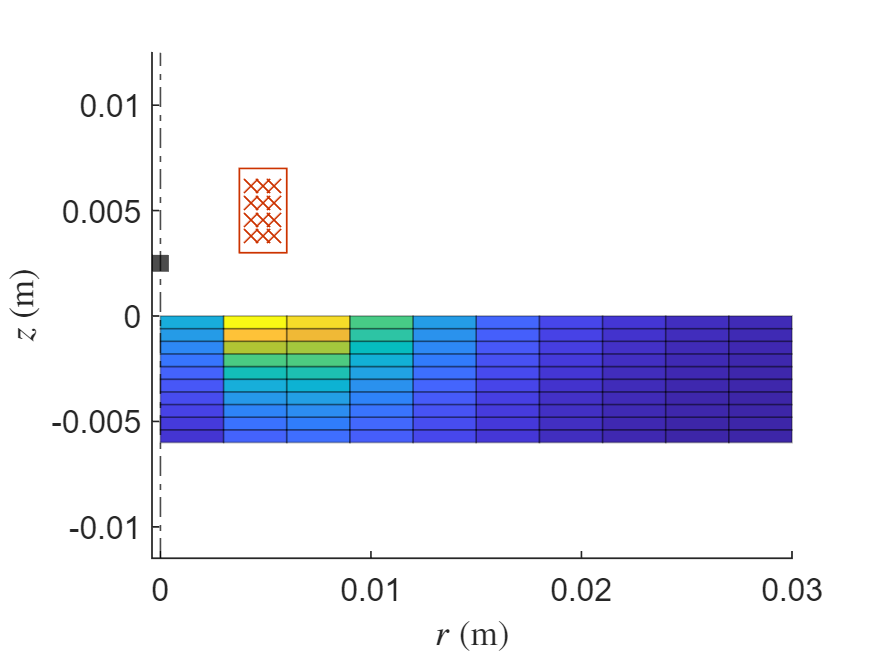

t = 0.3e-3; % (s)
[~,k] = min(abs(t - Model.time_domain.t));
PlotWorld2D(Model, EM, Sensor, abs(Model.time_domain.J(:,:,k)) );

clf
clear t k

## Compare with FEA

#### Magnetic flux density

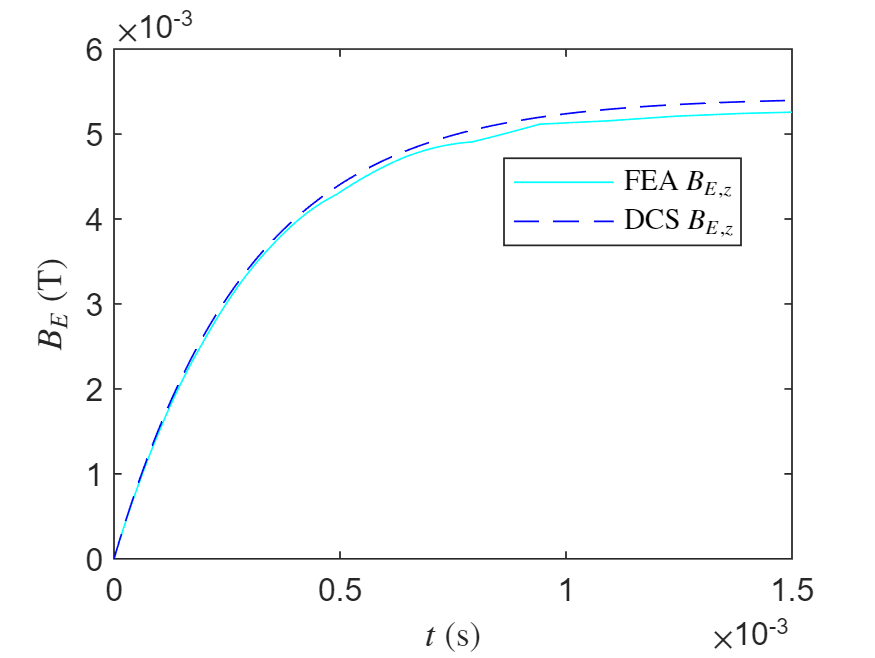

data = readmatrix('FEA_data/B_Air.csv', 'CommentStyle','%');
data = reshape(data(3:end), 3, []);
FEA.t = data(1,:);
FEA.B_E_r = data(2,:);
FEA.B_E_z = data(3,:);
data = readmatrix('FEA_data/B_Mo.csv', 'CommentStyle','%');
data = reshape(data(3:end), 3, []);
FEA.B_C_r = data(2,:) - FEA.B_E_r;
FEA.B_C_z = data(3,:) - FEA.B_E_z;

plot(FEA.t, FEA.B_E_z, 'c-', 'DisplayName','FEA $B_{E,z}$'); hold on
plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_E(2,1,:)), 'b--', 'DisplayName','DCS $B_{E,z}$');
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_E$ (T)", 'Interpreter','latex')
hold off

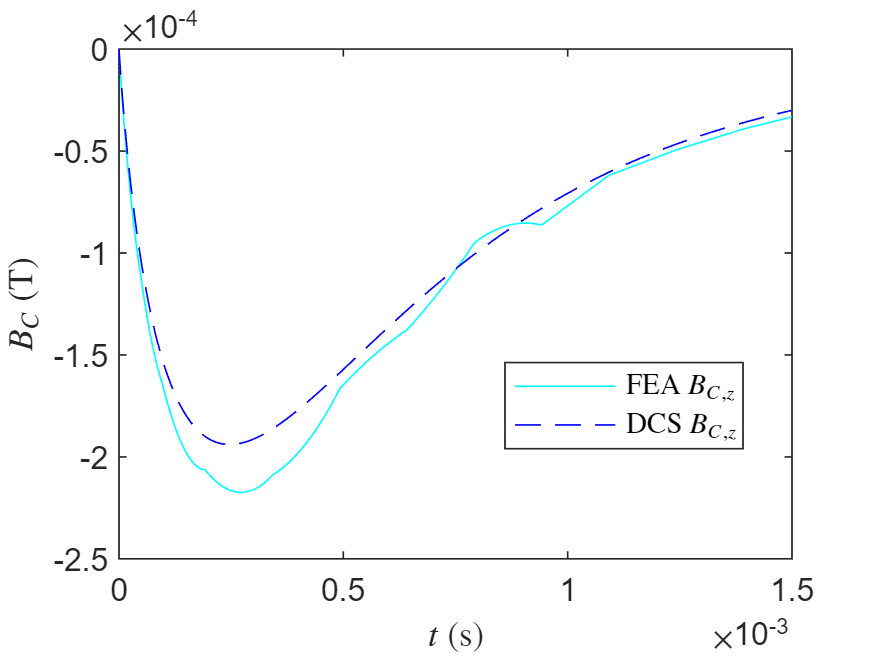

clf

plot(FEA.t, FEA.B_C_z, 'c-', 'DisplayName','FEA $B_{C,z}$'); hold on
plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_C(2,1,:)), 'b--', 'DisplayName','DCS $B_{C,z}$');
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_C$ (T)", 'Interpreter','latex')
hold off

clf

FEA_B_C = interp1(FEA.t, FEA.B_C_z, Sensor.time_domain.t);
DCS_B_C = squeeze(Sensor.time_domain.B_C(2,1,:));
[error, i] = maxk(abs(DCS_B_C - FEA_B_C), 100);
fprintf('B_C_z average relative error %e\n', mean(error ./ abs(FEA_B_C(i))));

B_C_z average relative error 1.147048e-01



clear data FEA_B_C DCS_B_C error i

## Material Sweep

#### Solve in time domain

materials      = ["Ti"    "Zn"   "Mo"   "Al"   "Cu"  ];
conductivities = [0.238e7 1.69e7 1.91e7 3.57e7 5.96e7];
colors         = ['r'     'g'    'b'    'k'    'y'   ];

hold on
for i = 1:numel(materials)
    material = materials(i);
    Model.conductivity = conductivities(i) * ones(1,Model.num_elms);
    c = colors(i);

    mu_0 = 4*pi*1e-7; % (H/m)
    GoverningEquation.Sigma = mu_0 * diag(Model.conductivity);

    [Model, EM, Sensor] = SolveTimeDomain2D(GoverningEquation, Model, EM, Sensor);

    t = Sensor.time_domain.t;
    B_z = Sensor.time_domain.B_E(2,1,:) + Sensor.time_domain.B_C(2,1,:);
    plot(t, squeeze(B_z), '-', 'DisplayName', material, 'Color',c);
end

solve in time domain took 1.67 seconds
solve in time domain took 0.38 seconds
solve in time domain took 0.36 seconds
solve in time domain took 0.29 seconds
solve in time domain took 0.27 seconds


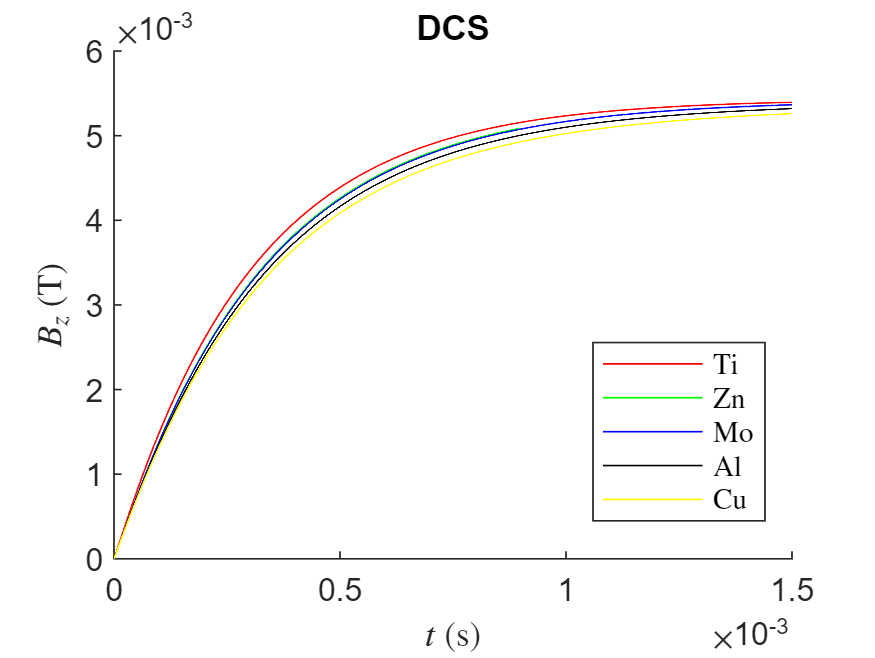

title('DCS')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_z$ (T)", 'Interpreter','latex')
hold off

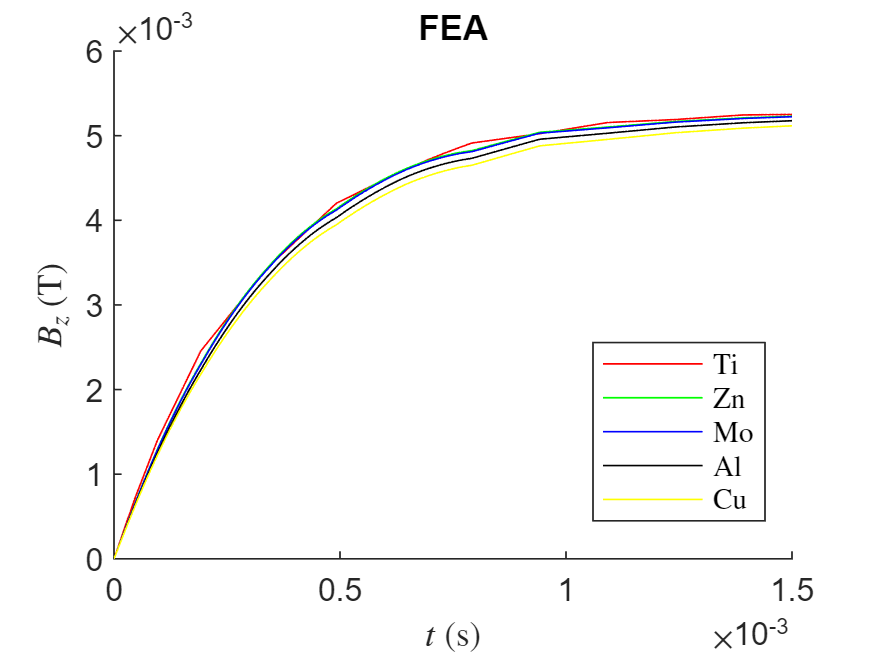

clf

hold on
for i = 1:numel(materials)
    material = materials(i);
    c = colors(i);

    data = readmatrix(sprintf('FEA_data/B_%s.csv',material), 'CommentStyle','%');
    data = reshape(data(3:end), 3, []);
    t = data(1,:);
    B_z = data(3,:);
    plot(t, squeeze(B_z), '-', 'DisplayName', material, 'Color',c);
end
title('FEA')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_z$ (T)", 'Interpreter','latex')
hold off

clf

clear materials conductivities colors i material c mu_0 t B_z data p